# Exergy Analysis Demo

Use `ExergyAnalysys` function to obtain the exergy balances and Table FP for one state of the plant

#### Read the Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the state of the plant to analyze

states=convertCharsToStrings(data.StateNames);
state=convertStringsToChars(states(5));

#### Get Exergy Analysis

Use function `ExergyAnalysis `to get the exergy balance por the selected state, and print de processes balance using function `ShowResults`

res=ExergyAnalysis(data,'State',state);
ShowResults(res,'Table','eprocesses');

Processes Exergy Table

Key         F(kW)       P(kW)       I(kW)      k(J/J)      η (%)
—————————————————————————————————————————————————————————————————
BLR       106.900      75.693      31.207      1.4123      70.81
TRB        65.670      52.447      13.223      1.2521      79.86
IHE         0.000       0.000       0.000      1.0000     100.00
PMP         2.447       2.093       0.354      1.1691      85.53
CND        12.116      12.116       0.000      1.0000     100.00
ENV       106.900      50.000      56.900      2.1380      46.77



#### Show the Diagram FP

Show the Diagram FP as graph using `ShowGraph` function

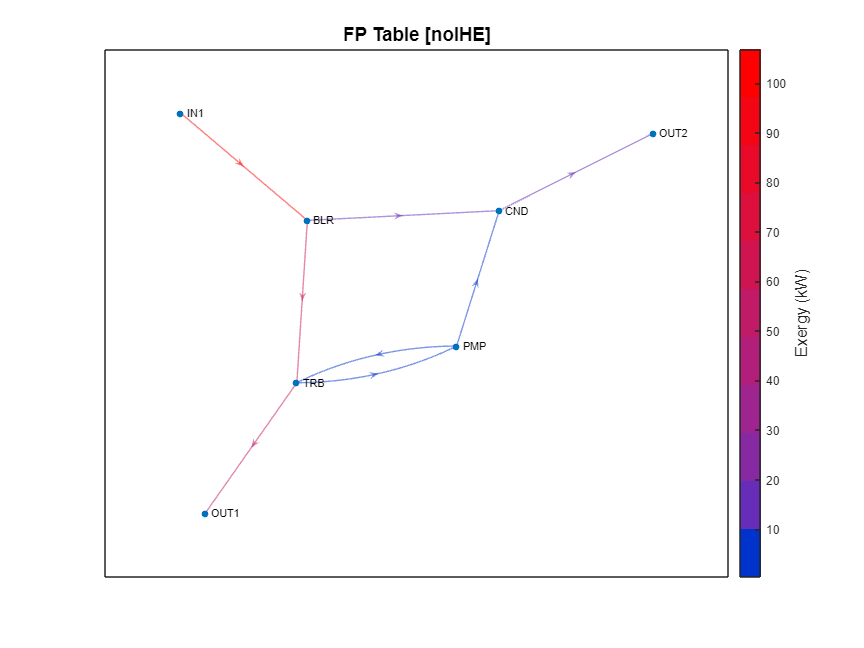

ShowGraph(res)